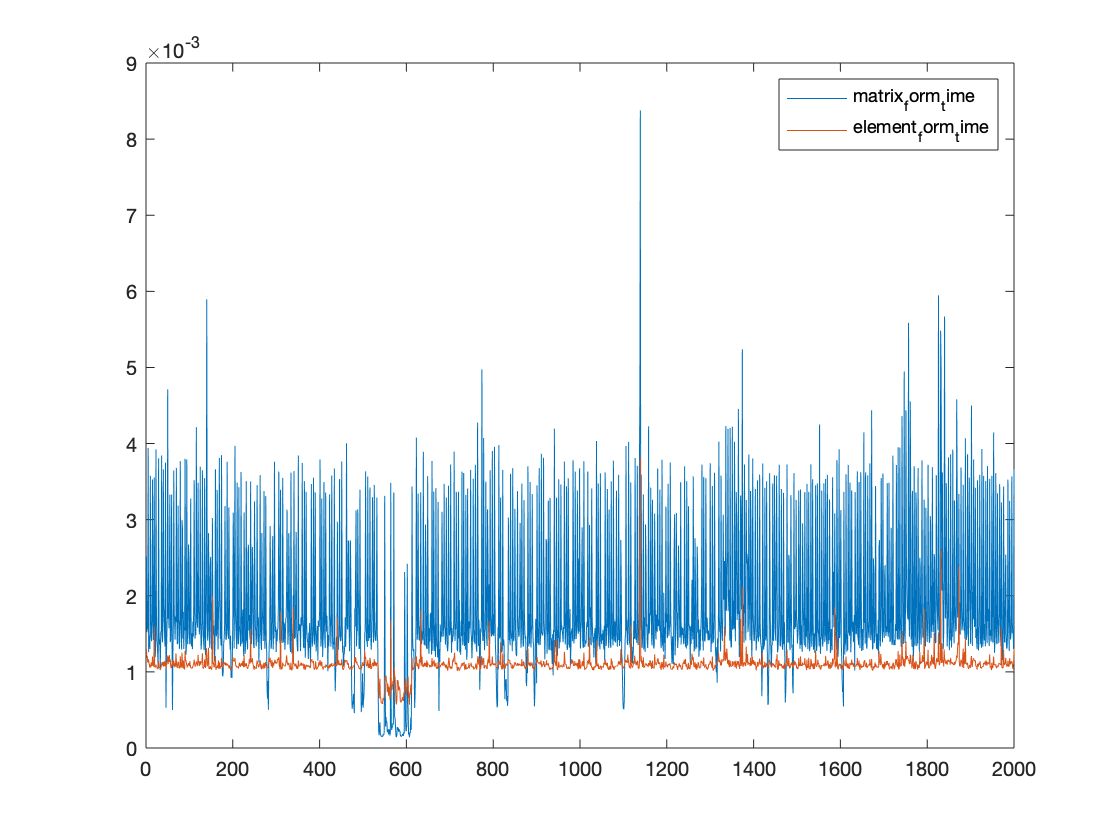

matrix_form_time = [];
element_form_time = [];
for i = 1:2000
    temp_tm = [];
    temp_te = [];
    for i = 1:100
        test_nodes(i).pose = rand(1, 3);
    
        tic
        neighbours = Extract_item(nodes, 'pose');
        dists = sqrt(diag(neighbours*neighbours') - 2*neighbours*pos' + pos*pos'); 
        t_m = toc;
        temp_tm = [temp_tm, t_m];
        
        tic
        dists = [];
        for i = 1:length(nodes)
            dists = [dists; nodes(i).pose - pos];
        end
        dists = vecnorm(dists, 2, 2);
        t_e = toc;
        temp_te = [temp_te, t_e];
    end
    matrix_form_time = [matrix_form_time; mean(temp_tm)];
    element_form_time = [element_form_time; mean(temp_te)];
end
plot(1:2000, matrix_form_time)
hold on
plot(1:2000, element_form_time)
legend('matrix_form_time','element_form_time')